# Dominic Riccoboni Individual Problem Set 7

%Function to minimize over [-10 10]
funHandle = @(x)15*sin(2*x).^2 + (x-2).^2; 

%Use a large population size for better performance
popsize = 100;

%Upper and lower bound constraints on x
lb = -10;
ub = 10;

%Make sure that the initial range covers all possible x values
init_pop_range = [lb;ub];

%Allow enough iterations to occur for the solution to fall into the correct region
MaxGen = 10000;

%Allow 10% elitism, 60% crossover, and plenty of mutation with relatively rapid shrinking
%of the standard deviation in the gaussian mutation scheme. This shrinking allows a lot of
%spread in the beginninng but once it finds the area around the global minimum, it starts
%to focus in on finding the local minimum
options = optimoptions('ga', 'InitialPopulationRange', init_pop_range,...
   'PopulationSize',popsize,'EliteCount', 10, 'MaxGenerations',MaxGen,...
  'CrossoverFraction',.6, 'MutationFcn', ... 
{@mutationgaussian, .5, 100}) %'ConstraintTolerance', 1e-4,

options =   ga options:

   Set properties:
               CrossoverFraction: 0.6000
                      EliteCount: 10
          InitialPopulationRange: [2×1 double]
                  MaxGenerations: 10000
                     MutationFcn: {@mutationgaussian  [0.5000]  [100]}
                  PopulationSize: 100

   Default properties:
             ConstraintTolerance: 1.0000e-03
                     CreationFcn: @gacreationuniform
                    CrossoverFcn: @crossoverscattered
                         Display: 'final'
                    FitnessLimit: -Inf
               FitnessScalingFcn: @fitscalingrank
               FunctionTolerance: 1.0000e-06
                       HybridFcn: []
         InitialPopulationMatrix: []
             InitialScoresMatrix: []
             MaxStallGenerations: 50
                    MaxStallTime: Inf
                         MaxTime: Inf
    Nonlinea



warning('off','all')
[x, fval] = ga(funHandle,1,[],[],[],[],lb,ub,[], options) 

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


x = 1.5783

fval = 0.1812

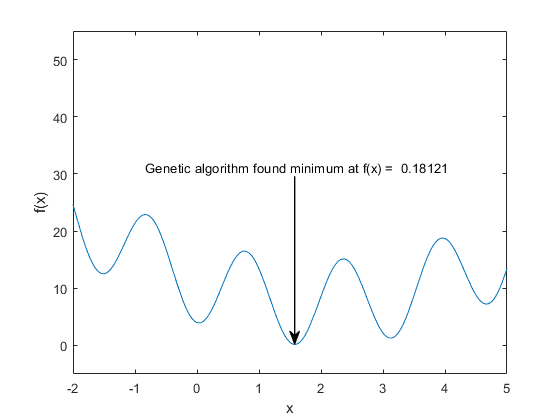

figure
fplot(funHandle, [-2 5])
ylim([-5 55])
xlabel('x')
ylabel('f(x)')

%Annotations
ax = gca;

% GA Result, the found minimum
LArr = .4; %Length of Arrow
PhiArr = deg2rad(90);
%Arrow Head
[xh, yh] = ds2nfu(ax,x, fval);
%Arrow Tail
xt = xh + LArr*cos(PhiArr);
yt = yh + LArr*sin(PhiArr);
annotation('textarrow',[xt xh],[yt yh],'String',['Genetic algorithm found minimum at f(x) =  ' num2str(fval)],'FontSize',10,'Linewidth',1)